# Craig's robotics book and learning from Robotics toolbox interactive script

2025 Nov 27 MatLab practice from chap 1 to 4

addpath('C:/Users/itsyu/GitHub/learning/src/plotframe') % dell pro AMD Ryzen i7 chip on windows system

addpath('/Users/peterchang/GitHub/learning/src/plotframe')  % macbook pro Apple M1 on OS X system

addpath('C:\Users\itsyu\MATLAB Drive\plotframe')

## Chap 2 Mapping and  other transforms

### 2.1 Rotation with 3D co-ordinate, based on an axis (z) using directional cosine projection

- 
$$^A_B R = \left[
\matrix{\hat{x}_B \cdot \hat{x}_A & \hat{y}_B \cdot \hat{x}_A & \hat{z}_B \cdot \hat{x}_A \cr 
\hat{x}_B \cdot \hat{y}_A & \hat{y}_B \cdot \hat{y}_A & \hat{z}_B \cdot \hat{y}_A \cr
\hat{x}_B \cdot \hat{z}_A & \hat{y}_B \cdot \hat{z}_A & \hat{z}_B \cdot \hat{z}_A }
\right]
=\left[
\matrix{^{A}\hat{x}_B & ^{A}\hat{y}_B & ^{A}\hat{z}_B}
\right]
=\left[
\matrix{^{B}\hat{x}_A^T & ^{B}\hat{y}_A^T & ^{B}\hat{z}_A^T}
\right]$$


- 
$$^{A}_BR = ^{B}_AR^T = ^{B}_AR^{-1}$$


-    $^{A}p_x = ^{B}\hat{x}_A \cdot ^{B}p$, $^{A}p_y = ^{B}\hat{y}_A \cdot ^{B}p$, $^{A}p_z = ^{B}\hat{z}_A \cdot ^{B}p$

#### Example 2.1:

3D Euler frame A: $\{A\} = \left[
\matrix{ \hat{x}_A & \hat{y}_A & \hat{z}_A}
\right]$, $\hat{x}_A = \left[ \matrix{1 & 0 & 0} \right]^T$ and $\hat{y}_A = \left[ \matrix{0 & 1 & 0} \right]^T$, and $\hat{z}_A = \left[ \matrix{0 & 0 & 1} \right]^T$.

3D Euler fram B: rotate about axis Z, where $\hat{z}_A = \hat{z}_B$, counter clock wise for $\theta = 30^o$

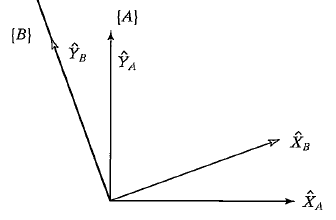

$^A_BR = \left [
\matrix{\cos{30} & -\sin{30} & 0 \cr \sin{30} & \cos{30} &0 \cr 0 & 0  & 1}
\right]$, thus $\{B\} = \left[ \matrix{
\sqrt{3}/2 & -1/2 & 0 \cr 
1/2 & \sqrt{3}/2 & 0 \cr 
0 & 0 & 1
}\right]$, as $\hat{x}_B = \left[ \matrix{ 
\sqrt{3}/2 \cr
1/2 \cr
0
}\right]$, specifically it is $^A\hat{x}_B$. $\hat{y}_B = \left[ \matrix{ 
-1/2 \cr
\sqrt{3}/2 \cr
0
}\right]$

Note that the first, second and third row is $^B\hat{x}_A ^T= \left[\matrix{
\sqrt{3}/2 & -1/2 &0
}\right] $, $^B\hat{y}_A ^T= \left[\matrix{
1/2 & \sqrt{3}/2 & 0
}\right] $, and $^B\hat{z}_A ^T= \left[\matrix{
0 & 0 & 1
}\right] $

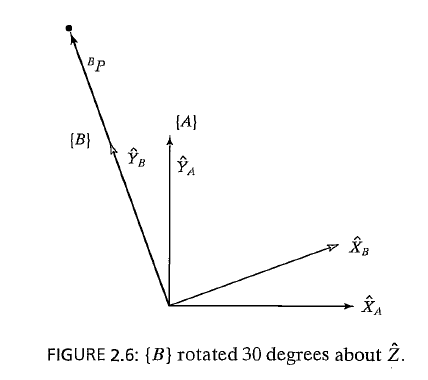

If we have a point p that is fixed in space, but only rotate the frame from frame:$\{A\}$ to frame: $\{B\}$, given $^{B}p = \left[ \matrix{
0 \cr 
2 \cr
0
}\right]$ assigned with this vector on against frame B. then for 


$$^{A}p = \left[ \matrix{
p_x \cr
p_y \cr
p_z
}\right] = 
 \left[ \matrix{
-1 \cr
\sqrt{3} \cr
0
}\right]=
\left[ \matrix{
\cos{30} & -\sin{30} & 0 \cr
\sin{30} & \cos{30} & 0 \cr
0 & 0 & 1
}\right]
\left[\matrix{
0 \cr
2 \cr
0
}\right]$$


% code example of using a rotational matrix from euler angles: eul
% eul2rotm([1/3*pi/2 0 0])   % remember in MatLab, euler is z-y-x!!!
% The above example of calculating:
p_frameB = [0 2 0]'     % point vector (translation vector) only in three numerals, not distinquishable

p_frameB =      0
     2
     0


p_frameA = eul2rotm([1/3*pi/2 0 0])*p_frameB    % practicing call direct use of eul2rotm (euler angle to rotational matrix) function

p_frameA =    -1.0000
    1.7321
         0


If we have a fixed point in space, and need just the translation... it is done directly by

p_frameA = [0 2 0]' + [3 1 0]'

p_frameA =      3
     3
     0



clear p*    % the above is example 2.1 on page 26 in Craig's book.

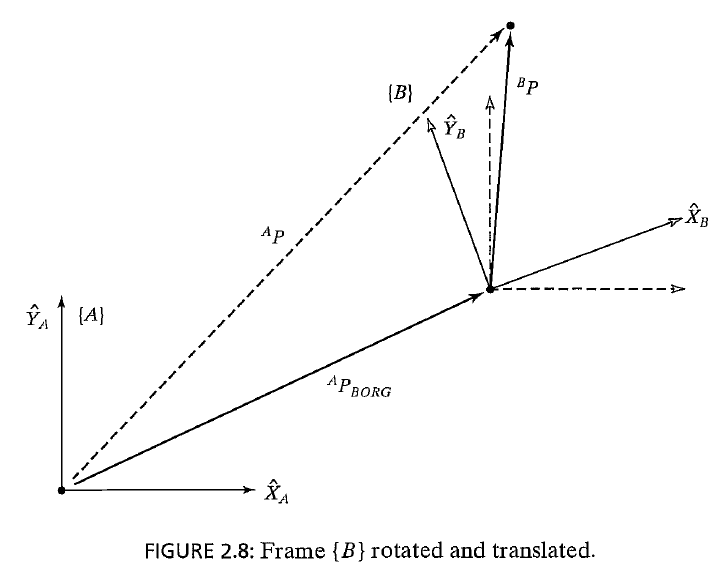

% using transformation operator to find directly the ^Ap presented if given
% ^Bp as like the example 2.2 on page 29
p_frameB = [3 7 0]';
p_Borg = [10 5 0]';   % frameB origin
frameB_orientation = so3([30/180*pi 0 0],'eul');
T_ab = se3(frameB_orientation,p_Borg') 

T_ab = se3
    0.8660   -0.5000         0   10.0000
    0.5000    0.8660         0    5.0000
         0         0    1.0000         0
         0         0         0    1.0000


p_frameA = T_ab.tform*([p_frameB' 1]');
p_frameA = p_frameA(1:3)

p_frameA =     9.0981
   12.5622
         0


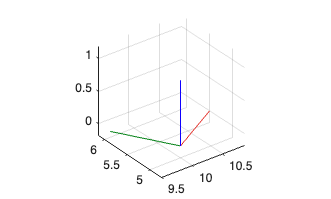

ax =   Axes with properties:

             XLim: [9.5000 10.8660]
             YLim: [4.7500 6.1160]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties



% clear all
figure
ax = plotTransforms(T_ab)   % viewing T_ab as a frame in space!!!

### 2.2 Translation with rotation becomes transformation

using standard vector addition: $^A p = ^ B p + ^A p_{BORG}$, as BORG= B's orgin

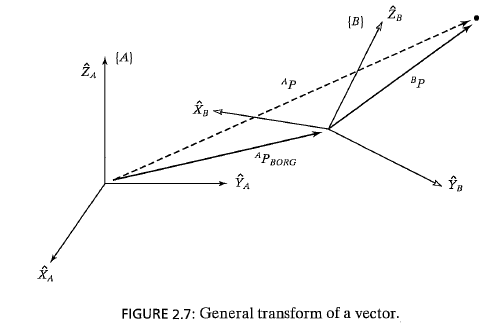

Since $^B p = ^A _B R ^B p$, then $^A p = ^A _B R ^B p + ^A p_{BORG}$ can be made into a general mapping from one frame making it:


$$\left[ \matrix{
^A p \cr
1
}\right] = \left[\matrix{
^A _B R & ^A p_{BORG} \cr
0,0,0 & 1
}\right] = \left[\matrix{
^B p \cr
1
}\right]$$


If using Euler-angle presentation $(\hat{x} -\hat{y}-\hat{z}, \alpha-\beta-\gamma)$


$$R_x \left(\alpha \right)=\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & \cos \alpha  & -\sin \alpha \\
0 & \sin \alpha  & \cos \alpha 
\end{array}\right\rbrack$$
 
$$R_y \left(\beta \right)=\left\lbrack \begin{array}{ccc}
\cos \beta  & 0 & \sin \beta \\
0 & 1 & 0\\
-\sin \beta  & 0 & \cos \beta 
\end{array}\right\rbrack$$
 
$$R_z \left(\gamma \right)=\left\lbrack \begin{array}{ccc}
\cos \gamma  & -\sin \gamma  & 0\\
\sin \gamma  & \cos \gamma  & 0\\
0 & 0 & 1
\end{array}\right\rbrack$$


can be used to combine into a local orentation R matrix.

Also, by convention, it is normal to put only one zero under the $^A_BR$ 3 by 3 matrix.

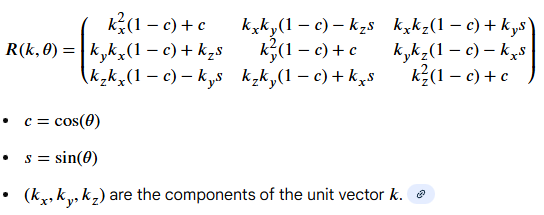

Or if we use $v\theta = (1-c\theta)$, and this is used to describe a rotation angle of $\theta$, along a orthonormal vector $k = \left[\matrix{
k_x \cr
k_y \cr
k_z
}\right]$.

$R_K(\theta) = \left[\matrix{
k_xk_xv\theta -c\theta & k_xk_yv\theta-k_zs\theta & k_xk_zv\theta+k_ys\theta \cr
k_yk_xv\theta +k_zs\theta & k_yk_yv\theta+c\theta & k_yk_zv\theta-k_xs\theta \cr
k_zk_xv\theta -k_ys\theta &k_zk_yv\theta+k_xs\theta & k_zk_zv\theta +c\theta
}\right]$, note that there exist a $K = \left[ \matrix{
0 & -k_z & k_y \cr
k_z & 0 & -k_x \cr
-k_y & k_x & 0
}\right]$ skey-symetric that generates $R_K(\theta) = I_3 + Ks\theta + K^2v\theta$, and also that this is most useful to describe later in it's deriviative.

#### Example 2.2: ploting and exercise using the most of robotics toolbox with pre-defined object

% example for defining a new frame and plot using the plotframe.m function

disp('Using universal frame as {A}, please input new frame origin: (x, y, z)')

Using universal frame as {A}, please input new frame origin: (x, y, z)


% newFrameOrigin = input('Enter the new frame origin as a vector [x, y, z]'': ');
newFrameOrigin = [3 14 0]

newFrameOrigin =      3    14     0


% Define the directional cosines for the transformation
% dirCos = eye(3); % Identity matrix as an example for no rotation

disp('Needs new frame {B} orientation, try to make it orthnormal, or can rotate it by providing random ZYX axis order which is also denoted as "Roll Pitch Yaw (rpy)."')

Needs new frame {B} orientation, try to make it orthnormal, or can rotate it by providing random ZYX axis order which is also denoted as "Roll Pitch Yaw (rpy)."


% disp('https://www.mathworks.com/help/robotics/ug/coordinate-transformations-in-robotics.html')


The following the code is from "plotframe" downloaded from MatLab center 

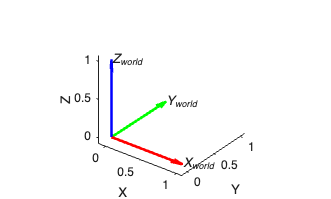

figure
axes( 'DataAspectRatio', [1 1 1], 'View', [37.5 30] )
plotframe( 'LabelBasis', true, ...
    'Labels', {'X_{world}','Y_{world}','Z_{world}'}, ...
    'TextProperties', {'FontAngle','italic'} )
xlabel( 'X' ), ylabel( 'Y' ), zlabel( 'Z' )
axis padded

Using robotics toolbox object SE2, SE3 or other euler angles for tranformation:

% se3 for orientation with position in 3D (declare a frame f1, f2... etc)
% so3 for orientation only, remember orientation is with 3 by 3 matrix
% (decalre a orentation, o1, o2... etc, this time using Euler angles)
% against 3D normal world frame.

% position is either p1, p2... etc [0 3 1] or [0;3;1] etc
% euler angles either eul1, eul2, associated at p1, p2 points

eul1 = [0 0 0];  % euler angle in z-y-x rotation sequence, roll-pitch-yaw
eul2 = 2*pi*rand(1,3);  % second rotation

p1 = newFrameOrigin;
p2 = [3 14 5];

f1 = se3(eul1,"eul",p1)      % f1 frame object created by orientation eul1 and point p1 

f1 = se3
     1     0     0     3
     0     1     0    14
     0     0     1     0
     0     0     0     1


f2 = se3(eul2,"eul",p2)

f2 = se3
   -0.7362   -0.3624    0.5716    3.0000
   -0.1500   -0.7362   -0.6599   14.0000
    0.6600   -0.5716    0.4876    5.0000
         0         0         0    1.0000


plot the same figure so to show the new frames "f1", and "f2" at locations "p1" and "p2".

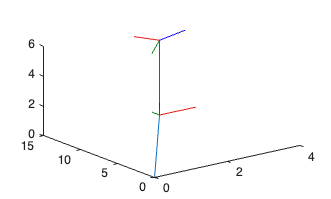

figure
hold on
%axes( 'DataAspectRatio', [1 1 1], 'View', [37.5 30] )
%rot = rotm(f1)           % rotm = extract rotational matrix from object "r" 
%plotframe('LabelBasis', true)   % using plotframe to have standard basis (feels like having eul0, p0, f0)
plotTransforms(f1)      % one can use plotTransform to plot 3D may be "un-rationed"

plotTransforms(f2)
plotline(p1,p2)
plotline([0 0 0],p1)    % calling personal function plotline.m (later) so to use similar way like plotframe.m
hold off

All the above scripts are using the most of Robotics toolbox, as using its opject to make a frame objects, and then using rotm(SE3) to extract rotation matrix, using trvec(SE3)  to extract tranlation matrix, and tform(SE3) to extract homogeneous tranformation. One more concept also uses quaternion $(a+b\hat{i}+c\hat{j}+d\hat{k})$, which is also a shorthand notation to present a full orientation for a "frame". It still needs a "position".

% remember: rotm = rotational_Matrix, trvec = translation_vector.
% it is a function from tranformation.rotm, and many others inside the se3
% object, that can be checked with "help se3"

% in Aerospace toolbox, there is a randrot(m) function, that can be used to
% make a randomized quaternion, or we can make random number angles in 2pi
% and random positions in 3D.
p = [zeros(3,1) round(10*rand(3,2))]    % location points vector {p} 3 by n, now in translation vector rows...

p =      0     0     1
     0     5     2
     0     2     1


q =[quaternion(0,0,0,0) randrot(1,2)];  % making quaternion objects {q} 1 by n matrix indexed, now in quaternion...
e = quat2rotm(q);                       % transforming the above {q} into numerical rotational matrices 3 by 3 by n-1
e(:,:,1) = eye(3)                       % re-assureing the first rotational matrix is eye(3) so to represent x-y-z

e = e(:,:,1) =

     1     0     0
     0     1     0
     0     0     1


e(:,:,2) =

    0.2477   -0.6786    0.6915
    0.3935   -0.5818   -0.7118
    0.8853    0.4484    0.1229


e(:,:,3) =

    0.9729   -0.0375    0.2281
    0.0266   -0.9620   -0.2716
    0.2297    0.2703   -0.9350


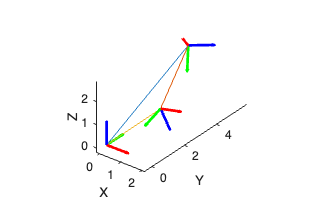


figure
axes( 'DataAspectRatio', [1 1 1], 'View', [37.5 30] )
plotframe(e(:,:,1),p(:,1))
xlabel( 'X' ), ylabel( 'Y' ), zlabel( 'Z' )
axis padded
hold on
plotframe(e(:,:,2),p(:,2))
plotframe(e(:,:,3),p(:,3))
%fr = se3()
plotline([0 0 0],p(:,2)')
plotline(p(:,2)',p(:,3)')
plotline([0 0 0],p(:,3)')


clear e*
clear f*
clear newFrameOrigin
clear p*
clear q

### 2.3 Transformation operator as se3 object and manipulation

using standard vector addition: $^A p = ^ B p + ^A p_{BORG}$, as BORG= B's orgin

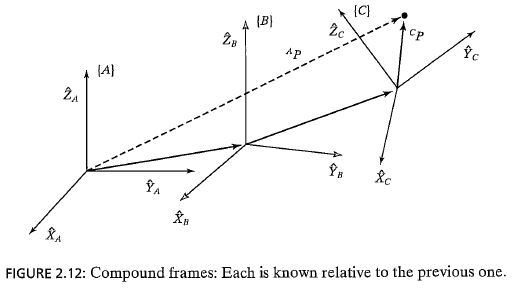

Full homogeneous transform (rotation + translation) is "Transfomed" using the operation(s): ($ ^A_B T$). Note that the most important operation is that it can combine multiple frame relations: $^A_C T = ^A_B T ^B_C T $.

the operation is using the Fig. 2.12, where $^Bp = ^B _C T ^C p$, as $^B _C T = \left[ \matrix{
^B _C R & ^BP_{CORG} \cr
0 & 1
}\right]$, showing that $^B p = ^B_C R ^Cp + ^Bp_{CORG} $, then using the same idea, as $^A_BT = \left[\matrix{
^A_BR & ^Ap_{BORG} \cr
0 & 1
}\right]$, thus it is true that:


$$^A_CT= 
\left[\matrix{
^A_BR^B_CR & ^B_AR^Bp_{CORG}+^Ap_{BORG} \cr
0 & 1
}\right]$$


Now that we're able to draw random frames and locate their relations, we'd be able to acquire how to move around the frame and to attach a robotics model onto the different frames, then later use d-h parameters...

#### Ex 2.3 Using frame transform to find the end effector (EOF) position and orientation representation

given a EOF position, orientation with it's SE3 object, in a random form peof = round(10*rand(3,1)'), rotm_eof

% Define three frame locations, the world frame, end effector frame - (designed to be) based
% on the frame of {B}, then the definition for the frame {B}, at the base
% origin of frame {B} and the actual frame {B} orientation.

% Note that all the rotation matrix (rotm), and the translation vector
% (trvec) are all defined as in world frame.

worldFrame = se3 % eye(4)

worldFrame = se3
     1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


eofFrame_World = se3(quat2rotm(randrot),round(10*rand(3,1)')) % end effector frame based on world frame

eofFrame_World = se3
    0.0641    0.9467   -0.3158    3.0000
    0.3307   -0.3187   -0.8883    3.0000
   -0.9416   -0.0475   -0.3335    3.0000
         0         0         0    1.0000


frameB = se3(eul2rotm([0 pi 0]),round(eofFrame_World.trvec*.8)) % frame b orientation and b_original

frameB = se3
   -1.0000         0    0.0000    2.0000
         0    1.0000         0    2.0000
   -0.0000         0   -1.0000    2.0000
         0         0         0    1.0000


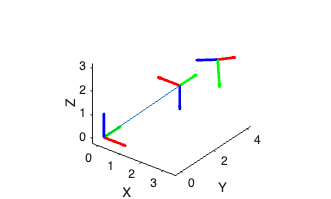


figure
axes( 'DataAspectRatio', [1 1 1], 'View', [37.5 30] )
plotframe(worldFrame.rotm, worldFrame.trvec)
xlabel( 'X' ), ylabel( 'Y' ), zlabel( 'Z' )
axis padded
hold on

plotframe(frameB.rotm, frameB.trvec)
plotframe(eofFrame_World.rotm, eofFrame_World.trvec)
plotline(worldFrame.trvec, frameB.trvec)

In defining and simulation, almost all the actual object, has to be declared in the "world" frame, and in the individual numbering, as like $^A_B R$, $^B_C R$, or $^A p_{1}$, $^Bp_{Aorg}$, all the vectors and matrix are either 3 by 1 and 3 by three, and on appearance its just numbers. One has to be sure how all the referred base frame is rotated and located!!!

% using all the different "world" based se3 object (orientation +
% position), finding the eof "Transformation" object based on frame {B}

!!! Both homogeneous transformation operator ($^A_B T$) and frames = rotation matrix (orientation) + translation vector (position) !!!! can both be used as the se3 object!!! 

% excercise of using object utilites as a frame (orientation + position)
dist(eofFrame_World,frameB)     % find the eucleadean distance between end effector to the frame b base

ans = 1.8576

interp(frameB,eofFrame_World,3) % interpolate points between two "point of orientation"

ans = 1×3 se3 array
ans(1,1) = 

   -1.0000         0    0.0000    2.0000
         0    1.0000         0    2.0000
   -0.0000         0   -1.0000    2.0000
         0         0         0    1.0000


ans(1,2) = 

   -0.6423    0.7586    0.1096    2.5000
    0.5515    0.5567   -0.6212    2.5000
   -0.5322   -0.3386   -0.7760    2.5000
         0         0         0    1.0000


ans(1,3) = 

    0.0641    0.9467   -0.3158    3.0000
    0.3307   -0.3187   -0.8883    3.0000
   -0.9416   -0.0475   -0.3335    3.0000
         0         0         0    1.0000


Using the same se3 object as a standard Homogenous Transform 

rotm(eofFrame_World)

ans =     0.0641    0.9467   -0.3158
    0.3307   -0.3187   -0.8883
   -0.9416   -0.0475   -0.3335


eofFrame_World * frameB         % multiplication of two "point + orientation" i.e. ^A_B T * ^B_C T 

ans = se3
   -0.0641    0.9467    0.3158    4.3899
   -0.3307   -0.3187    0.8883    1.2474
    0.9416   -0.0475    0.3335    0.3549
         0         0         0    1.0000


frameB

frameB = se3
   -1.0000         0    0.0000    2.0000
         0    1.0000         0    2.0000
   -0.0000         0   -1.0000    2.0000
         0         0         0    1.0000


### Exercises of chap 2

Ex 2.1 *A vector *$^Ap$* is rotated about *$\hat{Z}_A$* by *$\theta$* degrees and is subsequently rotated about *$\hat{X}_A$* by *$\phi$ *degrees. Give the rotation matrix that accomplishes these rotations in the given order.*

$R = 
\left[\matrix{
1 & 0 & 0 \cr
0 & c\phi & -s\phi \cr
0 & s\phi & c\phi
}\right]
\left[\matrix{
c\theta & -s\theta & 0 \cr
s\theta & c\theta & 0 \cr
0 & 0 & 1 
}\right]
$, with the result multiply out.

Ex 2.2 A vector $^Ap$ is rotated about $\hat{Y}_A$ by 30 degrees and is subsequently rotated about $\hat{X}_A$ by 45 degrees. Give the rotation matrix that accomplishes these rotations in the given order.

$R = 
\left[\matrix{
1 & 0 & 0 \cr
0 & c 45^o & -s 45^o \cr
0 & s 45^o & c 45^o
}\right]
\left[\matrix{
c 30^o & 0 & s 30^o \cr
0 & 1 & 0 \cr
-s30^o & 0 & c 30^o 
}\right]
$, using code:

% axis-angle notation in MATLAB of so3 object
ax1 = [0 1 0 deg2rad(30)];      % note the axis-angle that states the proportion of the axis is between 0~1 for [x y z theta]
ax2 = [1 0 0 deg2rad(45)];
rotm1 = so3(ax1,"axang");
rotm2 = so3(ax2,"axang");
ans = rotm2*rotm1      % checked with solution manual!

ans = so3
    0.8660         0    0.5000
    0.3536    0.7071   -0.6124
   -0.3536    0.7071    0.6124


Ex 2.3 *A frame {B} is located initially coincident with a frame {A}. We rotate {B} about *$\hat{Z}_B$* by *$\theta$* degrees, and then we rotate the resulting frame about *$\hat{X}_B$* by *$\phi$

*degrees. Give the rotation matrix that will change the descriptions of vectors from *$^BP$* to *$^AP$. Note this is Euleriang angle rotation!!! so the order is inverted from that of fixed angle x-y-z order!!!


$$R = 
\left[\matrix{
c\theta & -s\theta & 0 \cr
s\theta & c\theta & 0 \cr
0 & 0 & 1 
}\right]
\left[\matrix{
1 & 0 & 0 \cr
0 & c\phi & -s\phi \cr
0 & s\phi & c\phi
}\right]
$$


Ex 2.4 *A frame {B} is located initially coincident with a frame {A}. We rotate {B} about *$\hat{Z}_B$* by 30 degrees, and then we rotate the resulting frame about *$\hat{X}_B$* by 45*

*degrees. Give the rotation matrix that will change the description of vectors from *$^BP$* to *$^AP$*.*

% this is tried with eul so3 object with sequence!!!
eul1 = [deg2rad(30) 0 0];   % notice the eulerian definition is [z-y-x] for default
eul2 = [0 0 deg2rad(45)];
rotm1 = so3(eul1,"eul");
rotm2 = so3(eul2,"eul");
ans = rotm1*rotm2       % notice the straight forward roder of transformation!! revers of axis-angle!!

ans = so3
    0.8660   -0.3536    0.3536
    0.5000    0.6124   -0.6124
         0    0.7071    0.7071


Ex 2.5 *Find and explain the eigenvalue and eigenvectors of a rotational matrix *$^A_BR$*.*

let us use a general $R$, by definition of eigenvalue $\lambda$, or a any vector (eigenvector) $u$

$Ru=\lambda u$, so that $||Ru||^2 = ||\lambda u||^2$, and therefore

$(Ru)^T(Ru)=\lambda^2||u||^2$, such that $u^TR^TRu = \lambda^2 ||u||^2$, given $R^TR = I$, this leads to

$||u||^2 = \lambda^2||u||^2$, then this makes $\lambda = \pm1$.

and now if we have $R_{3 \times 3}$, then $\lambda = 1, e^{\pm i\theta}$. if $\lambda = 1$, what is this eigen vector $Ru=u$ mean? as this eigenvector is the same, this vector is the rotational axis!!

Ex 2.6 derive $R_K(\theta) = \left[\matrix{
k_xk_xv\theta -c\theta & k_xk_yv\theta-k_zs\theta & k_xk_zv\theta+k_ys\theta \cr
k_yk_xv\theta +k_zs\theta & k_yk_yv\theta+c\theta & k_yk_zv\theta-k_xs\theta \cr
k_zk_xv\theta -k_ys\theta &k_zk_yv\theta+k_xs\theta & k_zk_zv\theta +c\theta
}\right]$ where $\hat{k} = \left[\matrix{
k_x \cr
k_y \cr
k_z
}\right]$ is a orthonormal (directional) vector, and a roational angle $\theta$.

genearator from mentioned above but most important: make a frame {A} whose $\hat{Z_A}$ axis is aligned with the direction $\hat{k} = \left[\matrix{
k_x & k_y & k_z
}\right]^T$, when the rotation matrix $R = \left[\matrix{
r_{11} & r_{12} & r_{13} \cr
r_{21} & r_{22} & r_{23} \cr
r_{31} & r_{32} & r_{33}
}\right]$ is transformed to the rotation about $\hat{k}$ with $\theta$degrees. So it can be written as $R = ^U_AR\left(rot(^A\hat{z_k},\theta)\right)^A_UR$. This is especially noted in the solution manual, that 

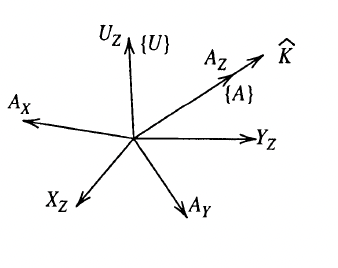

using the figure, it can be seen if we add a frame {A}, and align the $\hat{A}_Z$ axis to the vector $\hat{K}$, then rotate this angle with angle $\theta$. This operation relies on the transform such that $^U_AR=\left[\matrix{
A & D & k_x \cr
B & E & k_y \cr
C & F & k_z
}\right]$, so that $rot(^A\hat{z},\theta)=\left[\matrix{
c\theta & -s\theta & 0 \cr
s\theta & c\theta & 0 \cr
0 & 0 & 1
}\right]$, with $^R_UR=\left[\matrix{
A & B & C \cr
D & E & F \cr
k_x & k_y & k_z
}\right]$, thus the final $R\left(\hat{k},\theta\right)$ can be multiplied out, with use of:

$A^2 + B^2 +C^2 = 1$, $D^2 + E^2 + F^2 = 1$, and $\left[\matrix{
A & B & C
}\right]^T \cdot
\left[\matrix{
D & E & F
}\right] = 0$, $\left[\matrix{
A & B & C
}\right] \times
\left[\matrix{
D & E & F
}\right] = 
\left[\matrix{
k_x & k_y & k_z
}\right]$ , would derive the outcome.

ref: R. Paul textbook p.25 

Ex. 2.7 D*escribe (or program) an algorithm that extracts the equivalent angle and axis of a rotation matrix. Equation (2.82) is a good start, but make sure that your*

*algorithm handles the special cases *$\theta$* = 0° and *$\theta$* = 180°.*

ans1 = quat2rotm(randrot);      % rotational matrix made from 'randrot' (random rotation) in quaternion object form
ans2 = rotm2axang(quat2rotm(randrot))   % transform rotational matrix (rotm) into axis-angle (axang)

ans2 =     0.9824   -0.1581   -0.0998    3.0260


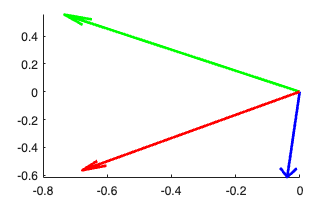


figure
plotframe(ans1,[0 0 0],1)

Ex 2.8-1* Write a subroutine that changes representation of orientation from rotationmatrix form to equivalent angle—axis form.. rm2aa, and aa2rm.*

% use the link: https://www.mathworks.com/help/robotics/ug/coordinate-transformations-in-robotics.html
% quaternion and randrot
% rotm2axang (input arguments in rotm form!!!)

use the documentation in [https://www.mathworks.com/help/robotics/ug/coordinate-transformations-in-robotics.html](https://www.mathworks.com/help/robotics/ug/coordinate-transformations-in-robotics.html)

Ex. 2.8-2 *Write a subroutine that changes representation of orientation from equivalent angle—axis form to rotational matrix form.*

% axang2rotm(input arguments in axang form!!!)

Ex. 2.9 *Write a subroutine that changes representation of orientation from axis-angle to fixed angle.*

*Ex. 2.10 Wirte a subroutine that changes representation of orientation from Euler angle to others.*

*Ex. 2.11 Under what condition do two rotation matrices representing finite rotations commute? A proof is not required.*

In two dimentions, the rotations matrix are like $\left[\matrix{
c\theta & -s\theta \cr
s\theta & c\theta
}\right]
\left[\matrix{
c\phi & -s\phi \cr
s\phi & c\phi
}\right] = 
\left[\matrix{
c(\theta+\phi) & -s(\theta+\phi) \cr
s(\theta+\phi) & c(\theta+\phi)
}\right]$and is commutable.

Ex. 2.12 *A velocity vector is given by *$^BV = \left[\matrix{
10.0 \cr 20.0 \cr 30.0
}\right]$, given $^A_BT=\left[\matrix{
0.866 & -0.500 & 0.00 & 11.0 \cr
0.500 & 0.866 & 0.00 & -3.0 \cr
0.000 & 0.000 & 1.00 & 9.0 \cr
0 & 0 & 0 & 1 
}\right]$, compute $^AV$

v_b = [10 20 30]'

v_b =     10
    20
    30


eul_ab = [deg2rad(30) 0 0 ]

eul_ab =     0.5236         0         0


R_ab = so3(eul_ab,"eul")

R_ab = so3
    0.8660   -0.5000         0
    0.5000    0.8660         0
         0         0    1.0000


T_ab = se3(R_ab,[11 -3 9])  % use 'transform(operator, pts[1 by 3]) to change co-ordiantes

T_ab = se3
    0.8660   -0.5000         0   11.0000
    0.5000    0.8660         0   -3.0000
         0         0    1.0000    9.0000
         0         0         0    1.0000


v_a = transform(R_ab,v_b')  % velocity is a "free vector" only ^A_BR needed!!!!

v_a =    -1.3397   22.3205   30.0000


v_a = v_a'

v_a =    -1.3397
   22.3205
   30.0000


Ex 2.13 *The following frame definitions are given as known*

$^U_AT=\left[\matrix{
0.866 & -0.500 & 0.000 & 11.0 \cr
0.500 & 0.866 & 0.000 & -1.0 \cr
0.000 & 0.000 & 1.000 & 8.0 \cr
0 & 0 & 0 & 1 
}\right]$, $^B_AT=\left[\matrix{
1.000 & 0.000 & 0.000 & 0.0 \cr
0.000 & 0.866 & -0.500 & 10.0 \cr
0.000 & 0.500 & 0.866 & -20.0 \cr
0 & 0 & 0 & 1 
}\right]$ and $^C_UT=\left[\matrix{
0.866 & -0.500 & 0.000 & -3.0 \cr
0.433 & 0.750 & -0.500 & -3.0 \cr
0.250 & 0.433 & 0.866 & 3.0 \cr
0 & 0 & 0 & 1 
}\right]$.

*Draw a frame diagram to show their arrangement qualitatively, and solve for *$^B_CT=^B_AT^A_UT^U_CT=^B_AT( ^U_AT^{-1})( ^C_UT^{-1})$ 

% first assign all se3 objects
eul_UA = [deg2rad(30) 0 0];
R_UA = so3(eul_UA,"eul");
T_UA = se3(R_UA,[11 -1 8])

T_UA = se3
    0.8660   -0.5000         0   11.0000
    0.5000    0.8660         0   -1.0000
         0         0    1.0000    8.0000
         0         0         0    1.0000



eul_BA = [0 0 deg2rad(30)];
R_BA = so3(eul_BA,"eul");
T_BA = se3(R_BA,[0 10 -20])

T_BA = se3
    1.0000         0         0         0
         0    0.8660   -0.5000   10.0000
         0    0.5000    0.8660  -20.0000
         0         0         0    1.0000



R_CU = [0.866 -0.500 0.000;0.433 0.750 -0.500;0.250 0.433 0.866];
% rad2deg(rotm2eul(R_CU));
eul_1 = deg2rad([0 0 30]);
eul_2 = deg2rad([30 0 0]);
R_CU = so3(eul_1,"eul")*so3(eul_2,"eul");
T_CU = se3(R_CU,[-3 -3 3])

T_CU = se3
    0.8660   -0.5000         0   -3.0000
    0.4330    0.7500   -0.5000   -3.0000
    0.2500    0.4330    0.8660    3.0000
         0         0         0    1.0000


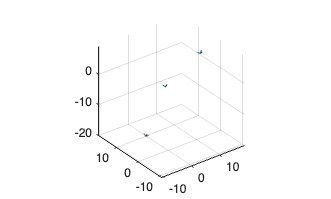


% using standard plottransform, not plotframe
plotTransforms([T_UA T_BA T_CU])

T_BC = T_BA*inv(T_UA)*inv(T_CU)

T_BC = se3
    0.5000    0.7500    0.4330   -6.5753
   -0.7500    0.6250   -0.2165   19.7877
   -0.4330   -0.2165    0.8750  -28.3187
         0         0         0    1.0000


Ex. 2.14 *Develop a general formula to obtain *$^A_BT$*, where, starting from initial coincidence, {B} is rotated by *$\theta$ *about *$\hat{K}$* where *$\hat{K}$ *passes through the point *$^AP$* (not*

*through the origin of {A} in general).*

$R = \left[\matrix{
rot_{\hat{K}}\theta 
}\right]$, and since $^A_BT = \left[\matrix{
^A_BR & ^AP_{Borg} \cr
0 & 1 
}\right]$, now that the axis-angle $\hat{K}$ does not pass through the frame {A}'s origin, so 1. Translate space so the axis passes through orign, 2. rotate, 3 translate back using: $x = R(x-P)+P$, so when x is now the origin of frame {B}, then $x = R(0-P)+P$, making $^AP_{Borg} = ^AP-^A_BR^AP$.

so generally speaking, it will be $T = \left[\matrix{
rot_{\hat{K}}\theta & ^AP-rot_{\hat{K}}\theta^AP \cr
0 & 1  
}\right] $

Ex. 2.15 *{A} and {B} frames diffe only in orientation. {B} is attained as follows: starting coincident with {A}, {B} is roated by *$\theta$ radians about univecotr $\hat{K}$, that is $^A_BR = ^A_BR_{K}(\theta)$*. Show that *$^A_BR = e^{k\theta}$, where $K = \left[\matrix{
0 & -k_z & k_y \cr
k_z & 0 & -k_x \cr
-k_y & k_x & 0
}\right]$.

Ex. 2.16 100 Hz vs 30 Hz consideration with $^AP = ^A_BR^B_CR^C_DR^DP$, such that $^DP$ is changing at 100 Hz but $^A_BR $, $^B_CR$, and $^C_DR$ are updated at 30 Hz. is it better to find $^A_DR$ in advance or sequentailly multiply out? which one has less multiplication and addition?

Ex. 2.17 *Cylindrical Coordiantes*

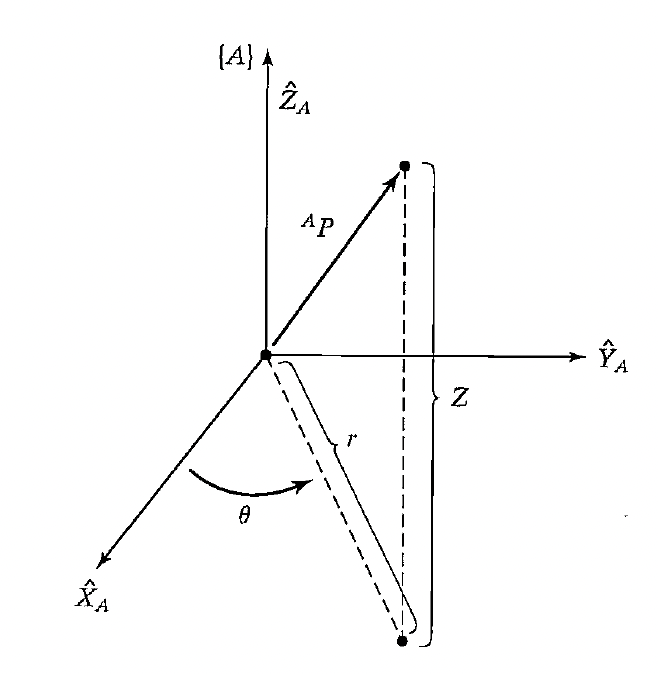


$$^AP=\left[\matrix{
rc\theta & rs\theta & z
}\right]^T$$


Ex. 2.18 *Spherical Coordiantes*

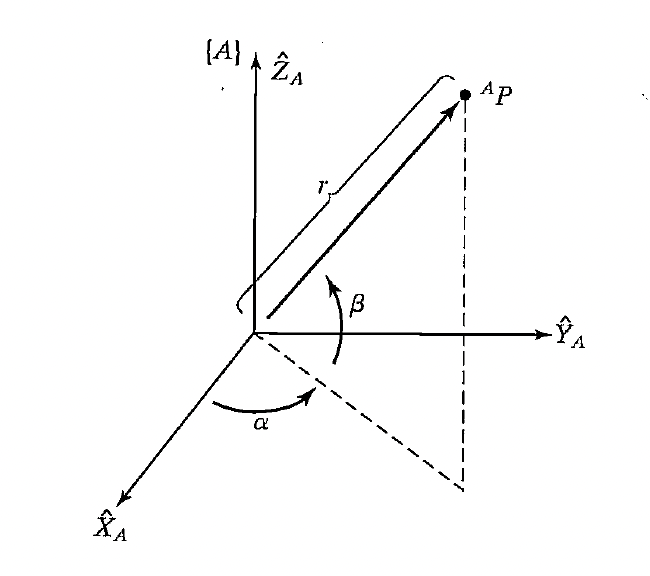


$$^AP = \left[\matrix{
rc\beta c\alpha & rc\beta s\alpha & rs\beta 
}\right]$$


Ex. 2.19 *An object is rotated about its *$\hat{X}$* axis by an amount *$\phi$,* and then it is rotated about its new axis *$\hat{Y}$*by an amount *$\psi$*. From our study of Euler angles, we know that the resulting orientation is given by *$R_x(\phi)R_y(\psi)$*. Whereas, if the two rotations has occured about axses os the fixed reference frame, the result would have been *$R_y(\psi)R_x(\phi)$. 

*It appears that the order of multiplication depends upon whether rotations are described relative to fixed axes or those of the frame being moved. It is more appropriate, however, to realize that in the case of specifying a rotation about an axis of the frame being moved, we are specifying a rotation in the fixed system given by : *

*Ex 2.20 Rodriques's formula *

*Ex. 2.21 for small angles *$\sin \theta = \theta$, $\cos \theta = 1$, *and *$\theta ^2 = 0$ *hold, derive Rotaitonal matrix equivalent to a rotation of \theta about a general axis \hat{K}.*

*Ex. 2.22 Show from above that two infinitesimal rotaions commute!*

*Ex. 2.23 Give an algorithm to construct the definition of a frame *$^U_AT$ *from three points *$^UP_1$, $^UP_2$, and $^UP_3$, *where the following is known about these points*

*    1. *$^UP_1$ *is at the origin of {A}*

*    2. *$^UP_1$ *lies somewhere on the positive X axis of {A}*

*    3. *$^UP_1$ *lies near the positive Y axis in the X-Y plane of {A}*

*Ex. 2.24 Prove Calyley's formula for proper orthonormal matrices*

*Ex. 2.25 Show that eigenvalues of a rotation matrix is 1, *$e^{\pm \alpha i}$

Ex 2.26 Prove that any  Euler-angle set is sufficient to express all possible rotation matrices.

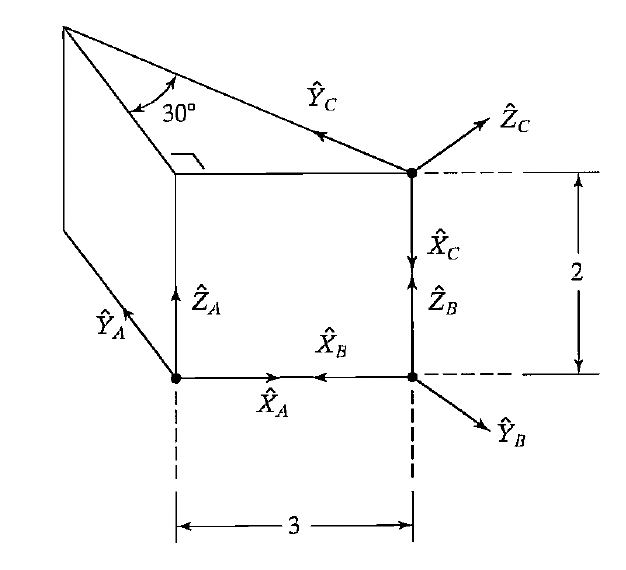

## Chap 3 Robot manipulator kenematics

Kinematic calculation with DH robot arm setting

### 3.1 D-H parameterization and frame attachment

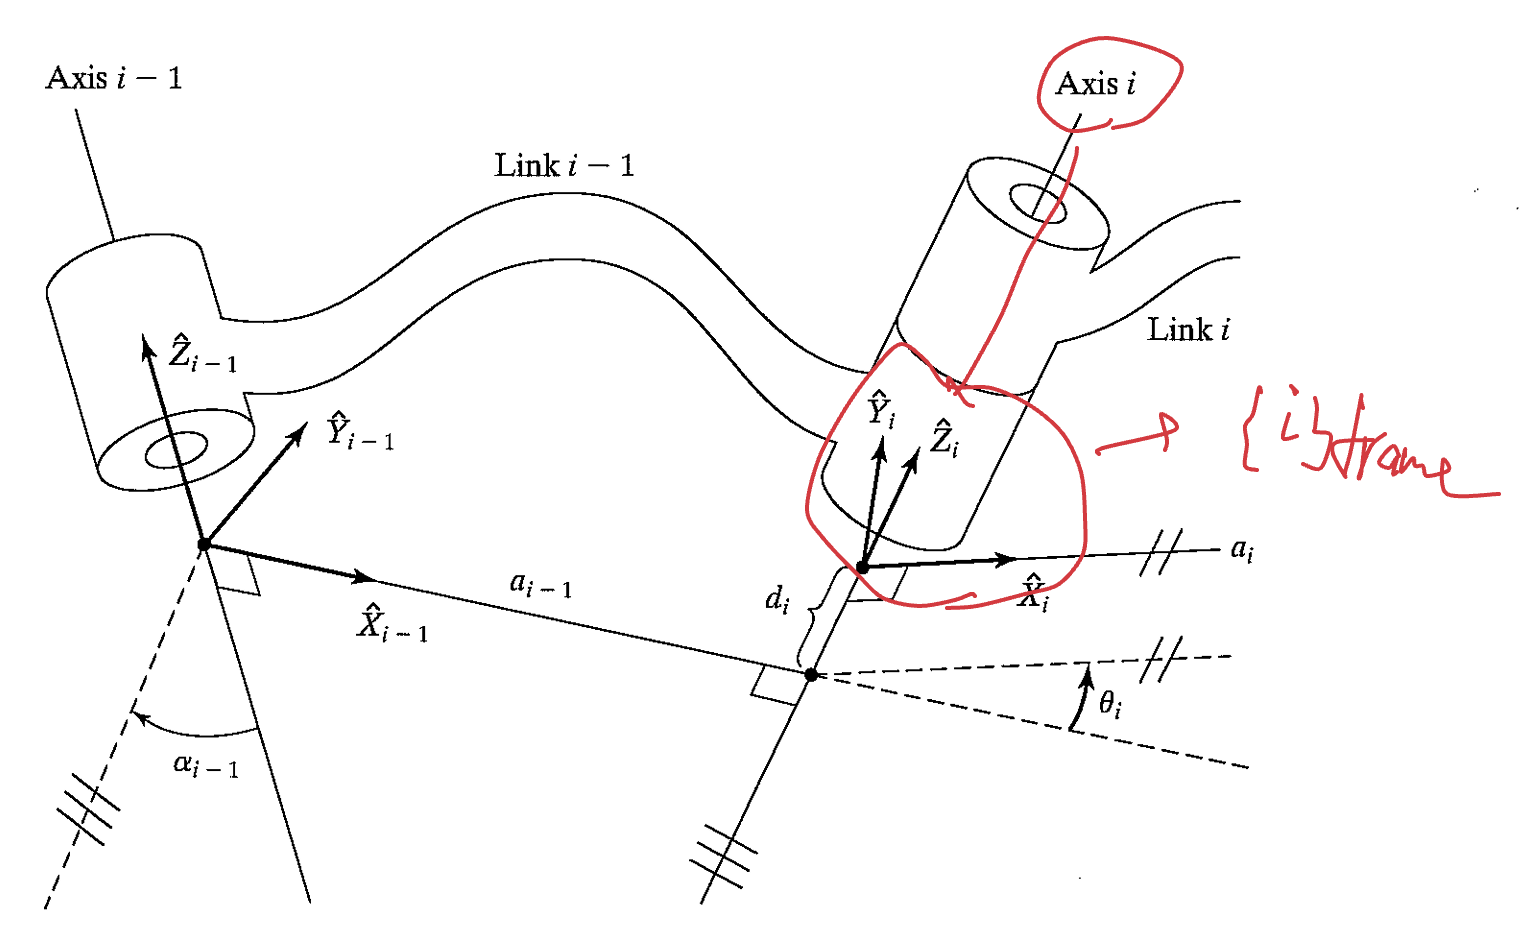

remeber the most important D-H parameters:

- $\alpha_{i-1}$ is the twist angle $\angle z_{i-1}z_i$, rotated about $\hat{x_{i-1}}$, however due to robot linkage, usually $z_{i-1}$ and $z_i$ are often $\pm 90^o (\pm \pi/2)$, as rotational joint or prismatic joint is linked

- $a_{i-1}$ is the link distance $|z_{i-1}z_i|$ along $\hat{x_{i-1}}$, but due to robot joint, usually if we coincide two frames of a joint, is is often zero

- $d_i$ is the link offest $|x_{i-1}x_i|$ along $\hat{z_i}$ as the new link is moved, due to joint movement (rotation/elongation) this is often a parameter!

- $\theta_i$ is the joint angle $\angle x_{i-1}x_i$ about $\hat{z_i}$, and since the most robot is revolute joints, this is often a paremeter!!!

The most important idea here is the linear transformation from the frame $\{i-1\}$ to $\{i\}$ for $^{i-1}_iT$, where we add three additional frames: $\{Q\}, \{R\}, and \{P\} $, such that {Q} is coincide with frame {i-1}, with only rotation $^{i-1}_{Q} T=R_{x_{i-1}}(\alpha_{i-1}) = 
\left[\matrix{
1 & 0 & 0  \cr
0 & c\alpha_{i-1} & -s\alpha_{i-1}  \cr
0 & s\alpha_{i-1} & c\alpha_{i-1} 
}\right]$, and $^{Q}_{R}T=D_{x_{i-1}}(a_{i-1})=^QP_{org}+\left[\matrix{
a_{i-1}x \cr
a_{i-1}y \cr
a_{i-1}z
}\right]
$, as well as the following $^{R}_P T ^{P}_{i}T = D_{z_i}(d_i)R_{z_i}(\theta_i)$, thus the total transform is:


$$R_{x_{i-1}}(\alpha_{i-1})D_{x_{i-1}}(a_{i-1})D_{z_i}(d_i)R_{z_i}(\theta_i) = \left[ \matrix{
1 & 0 & 0 & a_{i-1} \cr
0 & c\alpha_{i-1} & -s\alpha_{i-1} & 0 \cr
0 & s\alpha_{i-1} & c\alpha_{i-1} & 0 \cr
0 & 0 & 0 & 1
}\right]
 \left[ \matrix{
s\alpha_{i-1} & -s\alpha_{i-1} & 0 & 0\cr
s\alpha_{i-1} & c\alpha_{i-1} & 0  & 0\cr
0 & 0 & 1 & d_i \cr
0 & 0 & 0 & 1
}\right] = 
 \left[ \matrix{
c\theta_{i} & -s\theta_{i} & 0 & a_{i-1}\cr
s\theta_{i}c\alpha_{i-1} & c\theta_{i}c\alpha_{i-1} & -s\alpha_{i-1}  & -d_is\alpha_{i-1}\cr
s\theta_{i}s\alpha_{i-1} & c\theta_{i}s\alpha_{i-1} & c\alpha_{i-1} & d_ic\alpha_{i-1} \cr
0 & 0 & 0 & 1
}\right]$$


### 3.2 Standard Robot Arms 

This helps us to put frames of frame {i-1}, and frame {i} onto the link-joints.

D-H table is as such:

#### Example: R-P-R and R-R-P robot arm DH table

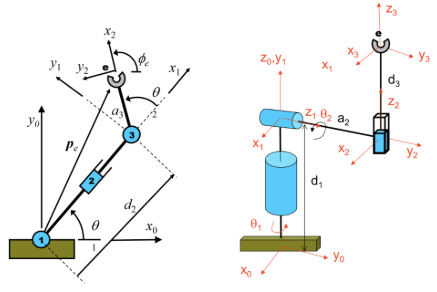

we will not use the assigned fixed frame on the picture, but use the Craig's definition:

for r-p-r

for r-r-p

## Chap 5 Jacobian: velocities and static forces

the most important rotation and translation frame transform and definition from base to tip

### 5.1 derivative against different points on frames transformations

a normal point Q (position) is described by its frame like in figure 1. for frame $\{A\}$ and frame $\{B\}$ Thus the final position's velocity is derived from $^A V_{Q} = ^A \frac{d}{dt}(^BQ)$, which from $^AQ = ^A_BR ^BQ+^AP_{Borg}$ is the standard transform like $^A_BT = \left[\matrix{
^A_B R & ^AP_{Borg} \cr
0 & 1
}\right]$. Due to the involvement of $RR^T=I_3$, it is clear that the privous non-rotating time constant Rotational matrix is now able to rotate with time, then it is true that there will be additional $^A\Omega_B \times ^AQ$ that is entering into the $^A V_Q$, that is needed to be computed when the frame $\{B\}$is rotating against $\{A\}$.  This introcues the skew-symmatric matrix, to use fo the cross product!

The previous skew-symmatric matrix $s = \left[\matrix{
0 & -s_x & s_y \cr
s_x & 0 & -s_x \cr
-s_y & s_x & 0
}\right]$, is then re-modeled by the derivative of $S = \dot{R}R^{-1} = \left[\matrix{
0 & -\Omega_z & \Omega_y \cr
\Omega_z & 0 & -\Omega_x \cr
-\Omega_y & \Omega_x & 0
}\right]$.

#### 5.2 Drivation of $^A V_p$ from three motions: frame translation, point translation and frame rotation

The final product of velocity component from frame to frame with moving and rotating frame$\{B\}$, is composed of three terms: $^AV_P = ^AV_{B_{org}}+^A_BR ^BV_P+^A\Omega_B \times ^AP$.

The first term is the moving tranlation frame $\{B\}$, so the velocity of the frame origin $^A\frac{d}{dt}\left(^AP_{Borg}\right)$. Then the second term is the moving $^B  \frac{d}{dt} \left(^BP\right) = ^BV_P$ , then reference to the frame$\{A\}$, so it is clear to be: $^A \frac{d}{dt}\left(^BP\right) = ^A_BR^BV_P$. Lastly there is the rotation of the frame$\{B\}$ against frame $\{A\}$, this term is simply the rotational velocity $^A \Omega_B \times ^AP$. Where there is the position of point $P = ^AP = ^BP$, but view from frame $\{A\}$ as frame $\{B\}$ is rotating.

#### Ex. discription of $\omega$

$\omega=\frac{d}{dt} R(t)= \lim_{\Delta t \rightarrow 0}\frac{R(t+\Delta t)-R(t)}{\Delta t}$, and let $R(t+\Delta t) = R_K (\Delta\theta)R(t)$, where $R_K(\theta) = \left[\matrix{
k_xk_xv\theta +c\theta & k_xk_yv\theta-k_zs\theta & k_xk_zv\theta+k_ys\theta \cr
k_yk_xv\theta +k_zs\theta & k_yk_yv\theta+c\theta & k_yk_zv\theta-k_xs\theta \cr
k_zk_xv\theta -sk_y\theta & k_zk_yv\theta+k_xs\theta & k_zk_zv\theta+c\theta
}\right]$, thus since $\Delta \theta \approx 0$, $s\Delta \theta = \sin(\Delta \theta)\approx \Delta\theta$, and $c\Delta \theta = \cos(\Delta\theta) \approx 1$, and $v\Delta \theta = 1-\cos(\Delta \theta) \approx 0$, then 

$\frac{d}{dt}R(t) = \lim_{\Delta t \rightarrow 0} \frac{1}{\Delta t}\left(
\left[\matrix{
1 & -k_z \Delta \theta & k_y\Delta \theta \cr
k_z \Delta \theta & 1 & -k_x \Delta \theta \cr
-k_y \Delta \theta & k_x \Delta \theta &1
}\right] -I_3\right)R(t)$, thus it becomes $\dot{R} = \left[\matrix{
0 & -k_z \dot{\theta} & k_y \dot{\theta}\cr
k_z \dot{\theta}& 0 & -k_x \dot{\theta}\cr
-k_y\dot{\theta} & k_x\dot{\theta} & 0
}\right]R(t)$, thus by left multiply $\dot{R(t)}R(t)^{-1}=\left[\matrix{
0 & -k_z & k_y \cr
k_z & 0 & -k_x \cr
-k_y & k_x & 0
}\right]\dot{\theta(t)} = 
\Omega=\left[\matrix{
0 & -\Omega_z & \Omega_y \cr
\Omega_z &0 & -\Omega_x \cr
-\Omega_y & \Omega_x &0
}\right] = K \times \dot{\theta}$. Where $\Omega = \left[\matrix{
\Omega_x & \Omega_y &\Omega_z
}\right]^T = \left[\matrix{
k_x \dot{\theta} & k_y \dot{\theta} & k_z \dot{\theta}
}\right]$.

### 5.3 link and joint variation

Recall that $^AV_Q = ^AV_{Borg}+^A_BR^BV_Q+^A\Omega_B\times (^A_BR^BQ)$, so that for a  link:(joint {i} to joint {i+1}) as show in the following figure

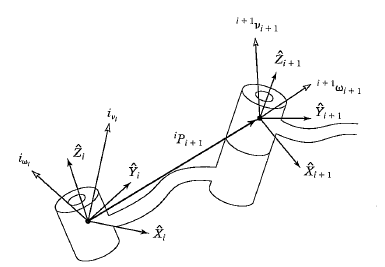

there are on the joint {i} ->($^iv_i$, $^i\omega_i$) pair, as well as the joint {i+1} -> ($^{i+1}v_{i+1}$, $^{i+1}\omega_{i+1}$) pair, they are related by means of the rigid body. On the velocity relationship end, it is clear that by using the above velocity relationship, $^iv_{i+1} = ^iv_i+^i\omega_i\times ^ip_{i+1}$. Due to the fact that the rigid body's frame center movement is $^iv_i$, with the link fixed as rigid, there is no change in $^ip_{i+1}$, but a rotation velocity $^i\omega_i \times ^ip_{i+1}$ is present.

The angular velocity is trickeir, as fist the $^i\omega$ are addable to become the next one: $^i\omega_{i+1} = ^i\omega_i + ^i_{i+1}R(\dot{\theta_{i+1}})^{i+1}\hat{Z}_{i+1}$. This pair becomes:

$\left\{\matrix{
^iv_{i+1} & = & ^iv_i & + &^i\omega_i\times ^ip_{i+1}  \cr
^i\omega_{i+1} & = & ^i\omega_i & + & ^i_{i+1}R \dot{\theta_{i+1}}^{i+1}\hat{Z}_{i+1}
}$, and pre-multiply $^{i+1}_iR$ the inverse/transpose of common $^i_{i+1}R$, is becomes:


$$\left\{\matrix{
^{i+1}v_{i+1} & = & ^{i+1}_iR\left(^iv_i+ ^i\omega_i\times ^ip_{i+1}\right) & + & \dot{d_{i+1}}^{i+1}\hat{Z}_{i+1} \cr
^{i+1}\omega_{i+1} & = & ^{i+1}_iR^i\omega_i & + & \dot{\theta_{i+1}}^{i+1}\hat{Z}_{i+1}
}$$


for revolute: $^{i+1} \omega_{i+1} = ^{i+1}_i R ^i \omega _i +\dot{\theta_{i+1}}^{i+1}\hat{Z_{i+1}}$, but if there is no revolution, there is no need to add the $\dot{\theta_{i+1}}$

for prismatic $^{i+1}V_{i+1} = ^{i+1}_i R  \left(V_i + ^i \omega_i \times ^iP_{i+1}\right)+\dot{d_{i+1}}^{i+1}\hat{z}_{i+1}$, also if there is no extension there is no need to add the $\dot{d_{i+1}}$

Note that this is used from the perispective that one starts with the base frame ${0}$, such that there is a translating all the velocity and rotational angular velocity to the last link.NOTE the $^{i+1}_iR$ is the transpose of the more common $^A_BR$, where we usually have $^0_1R$ and $^i_{i+1}R$ is the standard form!!!

#### Ex. R-R Jacobian matrix derive 

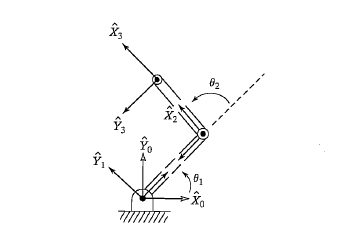

let us derive all the transformation:

$^0_1T = \left[\matrix{
c_1 & -s_1 & 0 & 0 \cr
s_1 & c_1 & 0 & 0 \cr
0 & 0 &1 & 0 \cr
0  & 0 & 0 & 1
}\right]$, with $^1_2T = \left[\matrix{
c_2 & -s_2 & 0 & l_1 \cr
s_2 & c_2 & 0 & 0 \cr
0 & 0 &1 & 0 \cr
0  & 0 & 0 & 1
}\right]$, as well as $^2_3T = \left[\matrix{
1 & 0 & 0 & l_2 \cr
0 & 1 & 0 & 0 \cr
0 & 0 &1 & 0 \cr
0  & 0 & 0 & 1
}\right]$.

thus it is useful to always use the base frame (fixed) $^0v_0 = \left[\matrix{
0 & 0 & 0
}\right]^T$, and $^0\omega_0=\left[\matrix{
0 & 0 & 0 
}\right]^T$.

It is clear that $^1\omega_1 = ^1_0R^0\omega_0 + \left[\matrix{
0 & 0 & \dot{\theta_1}
}\right]^T$, so we can begin to iterate to and locate $^1v_1$.

$^1v_1 =^1_0R\left( \left[\matrix{
0 \cr 0 \cr 0
}\right] + \left[\matrix{
0 \cr 0 \cr \dot{\theta_1}
}\right]\times\left[\matrix{
0 \cr 0 \cr 0
}\right]
\right)
 = \left[\matrix{
0 \cr 0 \cr 0
}\right]$.

Now be sure to iterate angular velocity first:

$^2\omega_2 = ^2_1R^1\omega_1 +\left[\matrix{
0 \cr 0 \cr \dot{\theta_2}
}\right]
= 
\left[\matrix{
0 \cr 0 \cr \dot{\theta_1}+\dot{\theta_2}
}\right]$, then find (NOTE it is not $^1_2R$, but the transpose!!!)

$^2v_2 = ^2_1R\left(^1v_1+^1\omega_1\times ^1P_{2}) = ^2_1R
\left(
\left[\matrix{
0 \cr 0\cr \dot{\theta_1}
}\right] \times
\left[\matrix{
l_1 \cr 0 \cr 0
}
\right]\right)
 =
\left[\matrix{
c_2 & s_2 & 0 \cr
-s_2 & c_2 & 0\cr
0 & 0 & 1
}\right] \left[\matrix{
0 \cr l_1\dot{\theta_1} \cr 0  
}\right] = 
\left[\matrix{
s_2l_1\dot{\theta_1} \cr c_2l_1\dot{\theta_1} \cr0
}\right]$.

so it is clear that we can iterate:

$^3\omega_3 = ^3_2R^2\omega_2 = 
\left[\matrix{
 0 \cr 0  \cr \dot{\theta_1}+\dot{\theta_2}
}\right]$, since $^2_3R = ^3_2R = I_3$


$$^3v_3 = ^3_2R\left(^2v_2+^2\omega_2\times ^2P_{3}) = I_3
\left(
\left[\matrix{
s_2l_1\dot{\theta_1} \cr c_2l_1\dot{\theta_1} \cr
0}\right]
+
\left[\matrix{
0 \cr 0\cr \dot{\theta_1}+\dot{\theta_2}
}\right] \times
\left[\matrix{
l_2 \cr 0 \cr 0
}
\right]\right)
 =
\left[\matrix{
s_2l_1\dot{\theta_1}  \cr
c_2l_1\dot{\theta_1} \cr
0 
}\right]+\left[\matrix{
0 \cr l_2(\dot{\theta_1}+\dot{\theta_2}) \cr 0  
}\right] = 
\left[\matrix{
s_2l_1\dot{\theta_1} \cr (c_2l_1+l_2)\dot{\theta_1}+l_2\dot{\theta_2} \cr 0
}\right]$$


now the most important part of finding the expression for $^0\omega_3$ and $^0v_3$. We need to pre-multipoly $^0_3R = ^2_3R ^1_2R ^0_1R$. Which is

$\left[\matrix{
c_1 & -s_1 & 0\cr
s_1 & c_1 & 0 \cr
0 & 0 & 1
}\right]
\left[\matrix{
c_2 & -s_2 & 0\cr
s_2 & c_2 & 0 \cr
0 & 0 & 1
}\right] I_3=\left[\matrix{
c_1c_2-s_1s_2 & -(s_1c_2+c_1s_2) & 0 \cr
s_1c_2+c_1s_1 & c_1c_2-s_1s_2 & 0 \cr
0 & 0 & 1
}\right]$ (note special case that this is commutative in 2D), and this turns out to be $\left[\matrix{
c_{12} & -s_{12} & 0 \cr
s_{12} & c_{12} & 0 \cr
0 & 0 & 1 
}\right]$, where $c_{12} = \cos(\theta_1 + \theta_2) = c_1c_2-s_1s_2$, ans so on. Making


$$^0v_3 = \left[\matrix{
c_{12} & -s_{12} & 0 \cr
s_{12} & c_{12} & 0 \cr
0 & 0 & 1 
}\right]
\left[\matrix{
s_2l_1\dot{\theta_1} \cr
 (c_2l_1+l_2)\dot{\theta_1}+l_2\dot{\theta_2} \cr
 0
}\right] = 
\left[\matrix{
c_{12}s_2l_1 \dot{\theta_1} -s_{12}c_2l_1\dot{\theta_1}-s_{12}l_2\dot{\theta_1}-s_{12}l_2\dot{\theta_2} \cr
s_{12}s_2l_1\dot{\theta_1} +c_{12}c_2l_1\dot{\theta_1}+c_{12}l_2\dot{\theta_1}+c_{12}l_2\dot{\theta_2} \cr
0
}\right] = 
\left[\matrix{
s_1l_1\dot{\theta_1}-s_{12}l_2(\dot{\theta_1}+\dot{\theta_2}) \cr
c_1l_1\dot{\theta_1}+c_{12}l_2(\dot{\theta_1}+\dot{\theta_2}) \cr
0
}\right]$$


The best way to relate this to Jacobian is:


$$^0v_3 =  
\left[\matrix{
(s_1l_1-s_{12}l_2)\dot{\theta_1} + (-s_{12}l_2)\dot{\theta_2} \cr
(c_1l_1+c_{12}l_2)\dot{\theta_1} + (c_{12}l_2)\dot{\theta_2}  
}\right] = 
\left[\matrix{
(s_1l_1-s_{12}l_2) & -s_{12}l_2 \cr
(c_1l_1+c_{12}l_2) & c_{12}l_2
}\right]
\left[\matrix{
\dot{\theta_1} \cr
\dot{\theta_2}
}\right]$$


we will check this later using the standard Jacobian method. Recall that this is $^0v = ^0J(\Theta)\dot{\Theta}$, the standard velocity Jacobian that transforms from joint space $\dot{\Theta} \rightarrow \dot{X} = v$ to cartesian space.

### 5.4 Jacobian

Jacobian is first found if $\left\{\matrix{
y_1(t) = f_1(x_1(t), x_2(t),\dots x_n(t)) \cr
y_2(t) = f_2(x_1(t), x_2(t),\dots x_n(t)) \cr
\ddots \cr
y_m(t) = f_m(x_1(t), x_2(t),\dots x_n(t))
}$, for $Y = \left[\matrix{
y_1 & y_2 & 
\dots & y_m
}\right]^T$ and $X = \left[\matrix{
x_1 & x_2 & 
\dots & x_n
}\right]^T$, thus 

$\left\{\matrix{
\dot{y_1(t)} = \frac{d}{dt}f_1(x_1(t), x_2(t),\dots x_n(t)) = \frac{\partial f_1}{\partial x_1}\dot{x_1}+\frac{\partial f_1}{\partial x_2}\dot{x_2}+\dots +\frac{\partial f_1}{\partial x_n}\dot{x_n}\cr
\dot{y_2(t)} = \frac{d}{dt}f_2(x_1(t), x_2(t),\dots x_n(t)) = \frac{\partial f_2}{\partial x_1}\dot{x_1}+\frac{\partial f_2}{\partial x_2}\dot{x_2}+\dots +\frac{\partial f_2}{\partial x_n}\dot{x_n}\cr
\ddots \cr
\dot{y_m(t)} = \frac{d}{dt}f_m(x_1(t), x_2(t),\dots x_n(t))= \frac{\partial f_m}{\partial x_1}\dot{x_1}+\frac{\partial f_m}{\partial x_2}\dot{x_2}+\dots +\frac{\partial f_m}{\partial x_n}\dot{x_n}
}$, so it is clear it can be written as:

$\dot{Y} = \left[\matrix{
\frac{\partial f_1}{\partial x_1} & \frac{\partial f_1}{\partial x_2} & \dots &\frac{\partial f_1}{\partial x_n} \cr
\frac{\partial f_2}{\partial x_1} & \frac{\partial f_2}{\partial x_2} & \dots &\frac{\partial f_2}{\partial x_n} \cr
&\ddots & & \cr
\frac{\partial f_m}{\partial x_1} & \frac{\partial f_m}{\partial x_2} & \dots &\frac{\partial f_m}{\partial x_n} 
}\right]_{m \times n}
\dot{X}$, and thus Jacobian is $J_{ij} = \frac{\partial f_i}{\partial x_j} $, and therefore for our joint space $\Theta(t) = \left[\matrix{
\theta_1 & \theta_2 & \dots & \theta_6
}\right]^T$, the associated workspace, many times if we define $\nu = \left[\matrix{
v_x & v_y & v_z & \omega_x & \omega_y & \omega_z
}\right]^T$. Note this is usually: $^0 \nu$, showing that one uses the base frame to describe the end effector velocity and e-o-f angular velocity. Thus it is true that : $ $^0 \nu = ^0 J(\Theta) \dot{\Theta}$$.

In robotics use, we usually like $\nu = \left[\matrix{
v_{3\times1} \cr
\omega_{3\times1}
}\right]$, then $\left[\matrix{
^0v \cr
^0\omega
}\right] = \left[\matrix{
^0_nR & 0 \cr
0 & ^0_nR
}\right]
{^nJ(\Theta)}\dot{\Theta}$

#### Ex. using two link R-R manipulator to find the Jacobian, then confrim the velocity and anular velocity from privous example:

Since the x and y co-ordinate of the end effector is also a vector point: we can calculate it by tranforming the base co-ordinate (x=0, y=0) with the $^0_3T = (^0_1T^1_2T)^2_3T$, and find the final Location pair $^3p = \left[\matrix{x_3 & y_3 & z_3}\right]^T$ with $\left[\matrix{
c_1 & -s_1 & 0 & 0 \cr
s_1 & c_1 & 0 & 0 \cr
0 & 0 & 1 & 0 \cr
0 & 0 & 0 & 1
}\right]\left[\matrix{
c_2 & -s_2 & 0 & l_1 \cr
s_2 & c_2 & 0 & 0 \cr
0 & 0 & 1 & 0 \cr
0 & 0 & 0 & 1
}\right]\left[\matrix{
1 & 0 & 0 & l_2 \cr
0 & 1 & 0 & 0 \cr
0 & 0 & 1 & 0 \cr
0 & 0 & 0 & 1
}\right] = 
\left[\matrix{
c_{12} & -s_{12} & 0 & l_2c_{12}+l_1c_1 \cr
s_{12} & c_{12} & 0 & l_2s_{12}+l_1s_1 \cr
0 & 0 & 1 & 0 \cr
0 & 0 & 0 & 1
}\right]$ . 

So it is clear that $^0p = ^0_3T ^3p$, and this leads to:

$\left\{ \matrix{
x & = & l_1\cos(\theta_1) + l_2\cos(\theta_1+\theta_2) \cr
y & = & l_1\sin(\theta_1) + l_2\sin(\theta_1+\theta_2) 
} = 
\left\{{ \matrix{
x & = & c_1l_1 + c_{12}l_2 \cr
y & = & s_1l_1 + s_{12}l_2 
} $, we can take the partial derivative for the x, y-coordinate

$\left\{\matrix{
v_x = & \dot{x} = -l_1s_1 \dot{\theta_1} -l_2s_{12}\dot{\theta_1}-l_2s_{12}\dot{\theta_2} \cr
v_y = & \dot{y} = l_1c_1 \dot{\theta_1} +l_2c_{12}\dot{\theta_1}+l_2c_{12}\dot{\theta_2}
}$, showing that $^0v = \left[\matrix{
-l_1s_1-l_2s_{12} & -l_2s_{12} \cr
l_1c_1+l_2c_{12} & +l_2c_{12}
}\right]
\left[\matrix{
\dot{\theta_1} \cr
\dot{\theta_2}
}\right]
=
J(\Theta)\dot{\Theta}$.

### 5.4 Torque and Force static interaction

Now that the associated velocity and angular velocity $\left[\matrix{
v & \omega}\right]^T$ pair is ready, it is of most importance to find the static forces applied to the link and joints:

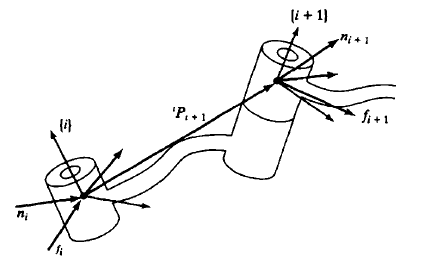

Where the force $^if_{i+1}$ and torque $^in_{i+1}$ are the associated applied force/moment pushing to the ${i+1}$link, so when the robot arm is static, it is true that:

$^if_i = ^if_{i+1}$ since the link is not moving, and 

$^in_{i} = ^in_{i+1}+^ip_{i+1}\times^if_i $. 

Note the addition of $r\times F$is the standard torque with lever!! This is used to transform the final acting force from the EOF to the base, so to find all the forces that is needed for the joint to stay static!!!


$$\left\{\matrix{
^if_i & = & ^i_{i+1}R(^{i+1}f_{i+1}) & \cr
^in_i & = & ^i_{i+1}R(^{i+1}n_{i+1}) &+ ^iP_{i+1}\times ^if_i
}$$


and finally the full needed torque to stablize the robot arm is:

$\tau_i = ^in_i^{T} \cdot ^i \hat{z_i}$, or $\tau_i = ^if_i^T \cdot ^i\hat{z_i}$. Depending on revolute or prismatic joints.

#### Ex. a 2-link manipulator, with a force acting on its end effector

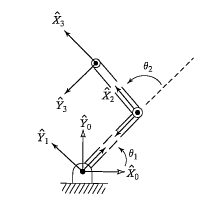

Assume there is the above 2 link manipulator, with a force $^3F=\left[\matrix{
f_x & f_y & 0 
}\right]^T$ appied to frame $\{ 3 \}$, what is the necessary torque $\tau = \left[\matrix{
\tau_1 & \tau_2
}\right]^T$ to keep the robot arm static?

This requires to iteratively use $\left\{ \matrix{
^if_i & = & ^i_{i+1}R ^{i+1}f_{i+1} & \cr
^in_i & = & ^i_{i+1}R ^{i+1}n_{i+1}+^iP_{i+1}\times^if_i
}$, starting from $^3f_3 = \left[\matrix{
f_x \cr
f_y \cr
0
}\right]$, and since $^2_3R = I_3$, $^2f_2 = ^3f_3$, making $^2n_2 = 0+\left[\matrix{
l_2\cr
0\cr
0
}\right]
\times
\left[\matrix{
f_x \cr
f_y\cr
0
}\right]$, where $^3n_3 = 0$. Finally:

$^2f_2 = \left[\matrix{
f_x \cr f_y \cr 0
}\right]$, $^2n_2 = \left[\matrix{
0 \cr 0 \cr l_2f_y
}\right]$. This leads to $^1f_1 = \left[\matrix{
c_1 & -s_2 & 0 \cr
s_2 & c_1 & 0 \cr
0 & 0 & 1
}\right]
\left[\matrix{
f_x \cr f_y \cr 0
}\right] = \left[\matrix{
c_1f_x-s_2f_y \cr
s_2f_x+c_1f_y \cr
0
}\right]$, $^1n_1 = \left[\matrix{
c_2 & -s_2 & 0 \cr
s_2 & c_2 & 0 \cr
0 & 0 & 1
}\right] 
\left[\matrix{
0 \cr 0 \cr l_2f_y
}\right]+\left[\matrix{
l_1 \cr 0 \cr 0
}\right]\times
\left[\matrix{
c_2f_x-s_2f_y \cr
s_2f_x+c_2f_y \cr
0
}\right]$, so:

$^1f_1  = \left[\matrix{
c_1f_x-s_2f_y \cr
s_2f_x+c_1f_y \cr
0
}\right]$, $^1n_1 = 
\left[\matrix{
0 \cr 0 \cr l_2f_y
}\right]+\left[\matrix{
0 \cr
0 \cr
l_1(s_2f_x+c_2f_y)
}\right]$, then lastly given $^0_1R = \left[\matrix{
c_1 & -s_1 & 0 \cr
s_1 & c_1 & 0 \cr
0 & 0 & 1
}\right]$, the final $^0f_0 = \left[\matrix{
c_1c_2f_x-c_1s_2f_y-s_1s_2f_x-s_1c_2f_y \cr
s_1c_2f_x-s_1s_2f_y+c_1s_2f_x+c_1c_2f_y \cr
0
}\right]$ with $^0n_0 =\left[\matrix{
c_1 & -s_1 & 0 \cr
s_1 & c_1 & 0 \cr
0 & 0 & 1
}\right] 
\left[\matrix{
0 \cr 0 \cr l_1s_2f_x+(l_2+l_1c_1)f_y
}\right]$, so that there's:

$^0f_0 = \left[\matrix{
c_{12}f_x-s_{12}f_y \cr
s_{12}f_x+c_{12}f_y \cr
0
}\right]$ and $^0n_0 = \left[\matrix{
0 \cr 0 \cr l_1s_2f_x+(l_2+l_1c_1)f_y
}\right]$. Using $\tau_1 = ^1n_1^T  {^1\hat{z_1}}$ and $\tau_2 = ^2n_2^T  {^2\hat{z_2}}$ , we see that

$\left\{\matrix{
\tau_1 & = & (l_1s_2)f_x+(l_1c_2+l_2)f_y \cr
\tau_2 & = & (0)f_x + (l_2)f_y
} = \left[\matrix{
l_1s_2 & l_1c_2+l_2 \cr
0 & l_2
}\right]\left[\matrix{
f_x \cr f_y
}\right]$.

Recall that in the previous example:

$^3v_3 =
\left[\matrix{
s_2l_1\dot{\theta_1} \cr (c_2l_1+l_2)\dot{\theta_1}+l_2\dot{\theta_2} \cr 0
}\right] \sim 
\left[\matrix{
s_2l_1 & 0 \cr
c_2l_1+l_2 & l_2
}\right]
\left[\matrix{
\dot{\theta_1} \cr
\dot{\theta_2}
}\right]$, and recall that $^3v = ^3J(\Theta)\dot{\Theta}$, it is clear that $\tau = ^3J(\Theta)^T \dot{\Theta}$

so that if we want $^0v_3 = ^0_3R ^3J(\Theta)\dot{\Theta}$, it can be seen: $^0J(\Theta) = ^0_3R^3J(\Theta)$.

In this case  $^0_1R = \left[\matrix{
c_1 & -s_1 & 0 \cr
s_1 & c_1 & 0 \cr
0 & 0 & 1
}\right]$, $^1_2R = \left[\matrix{
c_2 & -s_2 & o \cr
s_2 & c_2 & 0 \cr
0 & 0 & 1
}\right]$ and $^3_2R = I_3$, then $^0_3R = \left[\matrix{
c_{12} & -s_{12} & 0 \cr
s_{12} & c_{12} & 0 \cr
0 & 0 & 1
}\right]$, this checks:

$\left[\matrix{
c_{12} & -s_{12} \cr
s_{12} & c_{12}
}\right]
\left[\matrix{
l_1s_2 & 0 \cr
l_1c_2+l_2 & l_2 
}\right] = 
\left[\matrix{
l_1s_2c_{12}-l_1c_2s_{12}-l_2s_{12} & -l_2s_{12} \cr
l_1s_2s_{12}+l_1c_2c_{12}+l_2c_{12} & l_2c_{12}
}\right] = 
\left[\matrix{
-l_1s_1-l_2s_{12} & -l_2s_{12} \cr
l_1c_1 +l_2c_{12} & l_2c_{12}
}\right]$, showing the same example previously.


$$^0J(\Theta) = \left[\matrix{
-l_1s_1-l_2s_{12} & -l_2s_{12} \cr
l_1c_1+l_2c_{12} & l_2c_{12}
}\right]$$


### 5.5 Genearlization

So that it is clear where $\mu = \left[\matrix{
v \cr
\omega
}\right]$ are all the important states of the robot arm, at a "joint" or EOF which can be described with with respect to any frame, this includes the necessary force adaptation with virtual work principle, where all the work is conserved with a static robotics arm!! I.e.

$F\cdot\delta x= \tau \cdot \delta \Theta$, making it $F^T\delta x = \tau ^T \delta\Theta$, and so provided from our Jacobian definition: $\dot{x} = J(\Theta)\dot{\Theta}$, or that $\delta x = J(\Theta)\delta \Theta$, it is clear $F^T J(\Theta) \delta\Theta= \tau ^T \delta \Theta$, so that using $(AB)^T = B^TA^T$, it is clear $F^T J(\Theta) = \tau^T$ becomes $\tau = J^T(\Theta)F$ as shown in the previous example.

The most important generalization is that the velocity tranformation function $^A_BT_v$ and $^A_BT_f$, which now has a full transform for the velocity component $\nu = \left[\matrix{
v \cr
\omega
}\right]$ and force component $\mathcal{F} = \left[\matrix{
F \cr
N
}\right]$, where both are 6 by 1 vectors.

Recall that $\left\{\matrix{
^{i+1}\omega_{i+1} & =  & ^{i+1}_i R ^{i}\omega_i \cr
^{i+1}v_{i+1} & = & ^{i+1}_i R\left( ^{i}v_i + ^{i}\omega_i\times ^iP_{i+1}\right)
}$, and $\left\{\matrix{
^{i}f_{i} & = & ^{i}_{i+1} R^{i+1}f_{i+1} \cr
^{i}n_{i}& = & ^{i}_{i+1}R\left(^{i+1}n_{i+1}+^iP_{i+1}\times^if_i\right)
}$ . It is clear that

$\left\{\matrix{
^Bv_B & = & ^B_A R\left( ^Av_A +  ^A\omega_A\times ^AP_{Borg}\right) \cr
^B\omega_B & = & ^B_AR^A\omega_A
}$, and since $\overrightarrow{r}\times\overrightarrow{F} = -\overrightarrow{F}\times\overrightarrow{r}$, we can re-write this into

$\left[\matrix{
^Bv_B \cr
^B\omega_B
}\right]=\left[\matrix{
^B_A R & -^B_AR^AP_{Borg}\times \cr
0 & ^B_AR
}\right]
\left[\matrix{
^Av_A  \cr ^A\omega_A
}\right]$, defining $^B_AT_v = \left[\matrix{
^B_AR & -^B_AR^AP_{Borg}\times \cr
0 & ^B_AR
}\right]$, and notice that $P\times = \left[\matrix{
0 & -p_x & p_y \cr
p_x & 0 & -p_x \cr
-p_y & p_x & 0
}\right]$, the famous skew-symmetric cross product.

It is ealily shown that if we want to invert the transformation, such as $^A\nu _A = ^A_BT_v ^B\nu_B$, where $\nu = \left[\matrix{
v & \omega
}\right]^T$, then

$\left[\matrix{
^Av_A \cr
^A\omega_A
}\right] = \left[\matrix{
^A_B R & ^AP_{Borg}\times ^A_B R \cr
0 & ^A_BR
}\right]\left[\matrix{
^Bv_B \cr ^B\omega_B
}\right]$, and this is the standard definition. Notice that this rotationa matrix is more inline with our $^A_BR = \left[\matrix{
X_B\cdot X_A & Y_B \cdot X_A & \cdot \cr
X_B \cdot Y_A & \cdot & \cdot \cr
X_B\cdot Z_A & \cdot & Z_B \cdot Z_A
}\right] $, and this later makes the right hand side "simple velocities (tranlation/rotation) measuremed instantaneously. Similarily, for the force terms, where we've defined a general Force

$\left[\matrix{
^AF_A \cr ^AN_A
}\right]$, and it is clear that $\left[\matrix{
^AF_A \cr
^AN_A
}\right] = \left[\matrix{
^A_BR & 0 \cr
 ^AP_{Borg}\times ^A_BR & ^A_BR
}\right] 
\left[\matrix{
^BF_B \cr ^BN_B
}\right]$, such that there exist a $^A_BT_f = ^A_BT_v^T$.

#### Excercises:

The arm with three degrees of freedom shown in Fig. 3.29 is like the one in Example 3.3, except that joint l's axis is not parallel to the other two. Instead, there is a twist of 90 degrees in magnitude between axes {1} and {2}. Derive link parameters and the kinematic equations for $^W_B T$. Note that no $l_3$ need be defined.

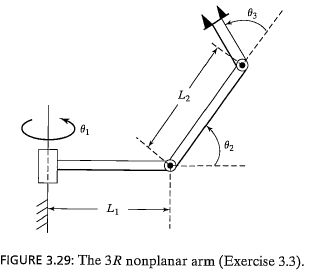

Find the Jacobian of the manipulator with three degrees of freedom from Exercise 3 of Chapter 3. Write it in terms of a frame {4} located at the tip of the hand and having the same orientation as frame {3}.

D-H table:

## Chap 6  Manipulator dynamics

### 6.1 intro

it is true that we are going to take another derivative of the velocity term to get our accelleation!!


$$^B\dot{V}_Q = \frac{d}{dt} \left(^BV_Q\right) =\lim_{\Delta t\rightarrow 0}\frac{^BV_Q(t+\Delta t)-^BV_Q(t)}{\Delta t}$$


## Appendix A:Used Functions

### Function 1: 

homogenious transform $^A_BT = \left[\matrix{
^A_BR & ^Ap_{Borg} \cr
0..0 & 1
}\right]$, using MatLab robotics toolbox

% Use MATLAB robotics toolbox's transform: se2, se3, so2, so3... and so
% on...

### Function 2:

a function to draw line of vector from HEAD to TAIL

function varargout = plotline( startPoint, endPoint)

phi = 0.5236

rx = so3
    1.0000         0         0
         0    0.8660   -0.5000
         0    0.5000    0.8660



%PLOTLINE Plot a 3-D Cartesian line between two points.
%     plotframe( )
%     plotframe( startPoint, endPoint )
%     plotframe( startPoint, endPoint, basisVectorLengths )
%     plotframe( __ , Parent=ax )
%     plotframe( __ , Name=Value )
%     hg = plotframe( __ )
% 
%   INPUTS
%   - startPoint        Defines the origin of the line. Default is zero zero
%                           , i.e., [0 0 0]. 
%   - endPoint          Defines the position of end of line 
%                           the origin. 1-by-3 or 3-by-1 numeric vector.
%                           Default is [1 1 1].
%   - basisVectorLengths    Length to plot each arrow (basis) of the
%                           coordinate frame. Scalar, 1-by-3, or 3-by-1 
%                           numeric vector. Default is 1.
%   - Name-Value Arguments
%       + Parent            Axes in which to plot. Scalar axes, group 
%                           (hggroup), or transform (hgtransform) object.
%                           Default is the current axes (gca).
%       + UpdateFrame       With UpdateFrame, the passed plot handles
%                           will be updated with the current parameters, 
%                           rather than creating a new plot. This is more 
%                           efficient and convenient for moving frames.
%                           Handle to an existing frame plot, outputted
%                           from a previous call to plotframe.
%       + MatrixIndexing    Depending on notation, either the columns or 
%                           the rows of rotationMatrix define the 
%                           orientation of the basis vectors. Text scalar, 
%                           either "columnmajor" or "rowmajor". Default is 
%                           row-major.
%       + LabelBasis        Whether the bases should be labelled, e.g., 
%                           "X", "Y", and "Z". Scalar logical. Default is 
%                           false.
%       + Labels            Text with which to label each basis, if 
%                           LabelBasis is enabled. Scalar, 1-by-3, or 
%                           3-by-1 text vector. Default is {'X','Y','Z'}.
%       + BasisColors       Color for each basis vector. Any color format
%                           accepted by MATLAB can be used, e.g., RGB 
%                           triplet [0 0 0], hexadecimal color code 
%                           #000000, or color name 'black' or 'k'. Specify
%                           multiple colors with an M-by-3 matrix where 
%                           each RGB color is a row, or as a 1-by-3 or 
%                           3-by-1 text array. Default is {'r','g','b'}.
%       + TextProperties    Custom properties for the basis labels. 
%                           Name-value arguments stored in a cell array of 
%                           alternating text property names and values, 
%                           e.g., {'FontSize',20,'FontWeight','bold'}.
%       + QuiverProperties  Additional name-value arguments are passed as
%                           properties of the Quiver charts used to plot 
%                           the basis vectors, e.g.,
%                           plotframe( LineStyle="-.", Marker="o" ).
%   OUTPUTS
%   - hg                    Group object (hggroup) containing handles to  
%                           the constituent parts of the coordinate frame 
%                           plot, i.e., the 3 Quiver and optional Text 
%                           objects.
% 
% 
%   See also QUIVER3, QUAT2ROTM, EUL2ROTM, MAKEHGTFORM, PLOTCAMERA

    arguments
        startPoint (1,3) double = [ 0, 0, 0]
        endPoint (1,3) double = [ 1, 1, 1 ]
    end
    
    %axis off
    x = [startPoint(1) endPoint(1)];
    y = [startPoint(2) endPoint(2)];
    z = [startPoint(3) endPoint(3)];
    line(x,y,z)
    drawnow

end